# Including conditional State-Jumps into your `IFDIFF` Trajectory

Normally, it is not possible to model conditional state jumps in the solution trajectory of an ODE using only the right-hand side (RHS). However, there are many processes where including such a jump can significantly simplify the underlying model—or is even essential. In these cases, `IFDIFF` offers a convenient workaround that ensures an accurate resulting trajectory while still allowing for the computation of sensitivities over the entire time span.

As an example we take the bouncing ball problem, an ODE system which models the height and velocity of a bouncing ball. The RHS looks as follows:

initPaths(); type bounceballRHS_cp.m


function dx = bounceballRHS_cp(~, x, p)
    dx = [x(2); -p(1)];
    if ifdiff_jumpif(x(1), -1)
        deltaH = -x(1) + eps(1)*(1/p(1)) * p(2)^2*x(2)^2;
        deltaV = -(1+p(2))*x(2);
        ifdiff_update([deltaH; deltaV]);
    end
end


It models the free fall of a ball.

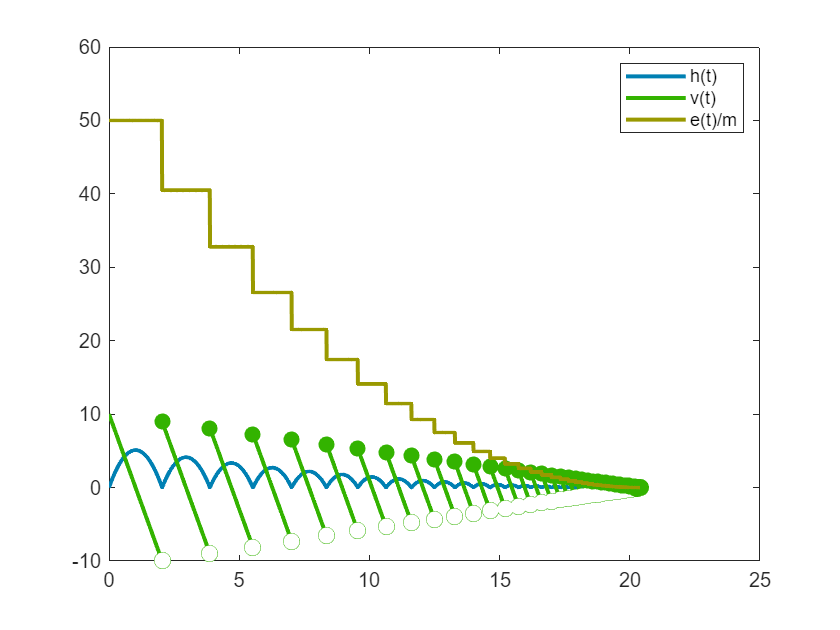

% Solve the bouncing ball problem and plot the solutions and sensitivities
clear;

solver = @ode15s;
options    = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);

g     = 9.807;
gamma = 0.9;
v0 = 10;
h0 = eps(1)*(1/g) * v0^2;
p = [g gamma];

t0 = 0;
tEnd = 20.39359; % zeno begins (analytically) at 20.3935964107270316 for these particular data
x0 = [h0; v0];

datahandle = prepareDatahandleForIntegration('bounceballRHS', 'solver', func2str(solver), 'options', options);
sol = solveODE(datahandle, [t0 tEnd], x0, p);


FDstep  = generateFDstep(size(x0,1), length(p));
sensFun = generateSensitivityFunction(datahandle, sol, FDstep, 'method', 'VDE', 'CalcGy', true, 'CalcGp', true);


T = t0:0.01:tEnd;
H = deval(sol, T, 1);
V = deval(sol, T, 2);
E = p(1)*H + (1/2) * V.^2;
plot(T, H, 'LineWidth', 2, 'DisplayName', 'h(t)', 'Color', [0 0.5 0.7]);
hold on;
plotSolWithJumps([t0 tEnd], sol, 2, 'v(t)', [0.2 0.7 0], struct(), 'LineWidth', 2);
plot(T, E, 'LineWidth', 2, 'DisplayName', 'e(t)/m', 'Color', [0.6 0.6 0]);
hold off;

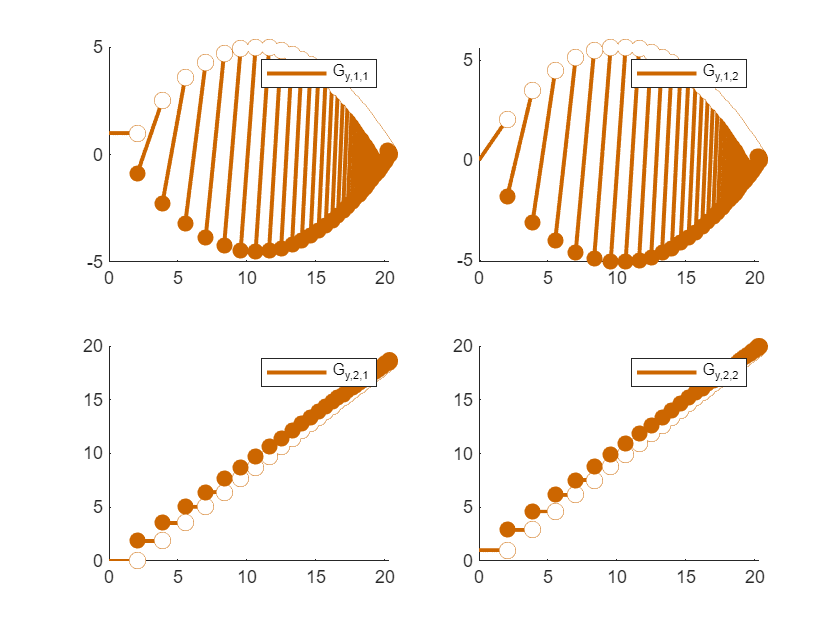

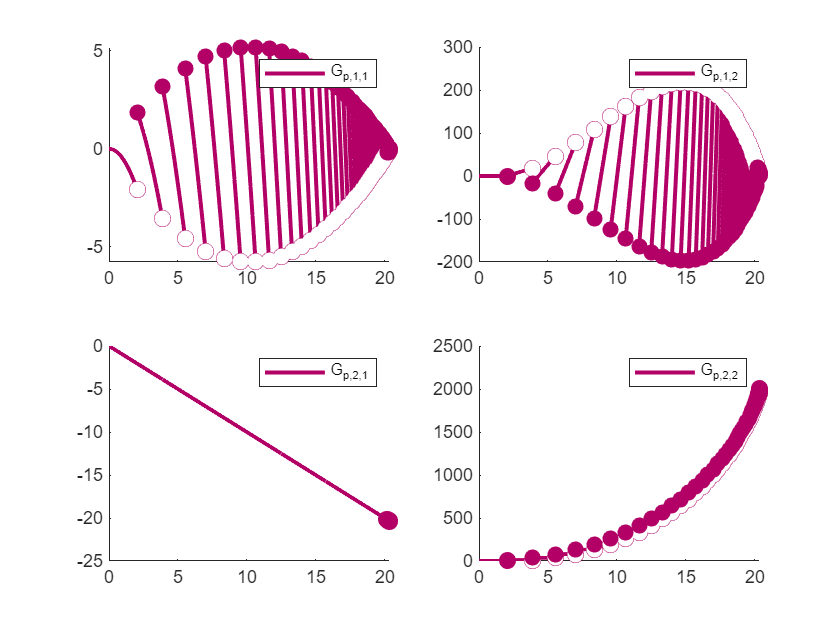

plotSensitivitiesSwitched(sol, sensFun, [t0 tEnd], struct(), struct(), 'LineWidth', 2);